## Aufgabe 4: Programmierung

### Darstellung eines Rechtecksignals über das Überlagern von Sinusschwingungen

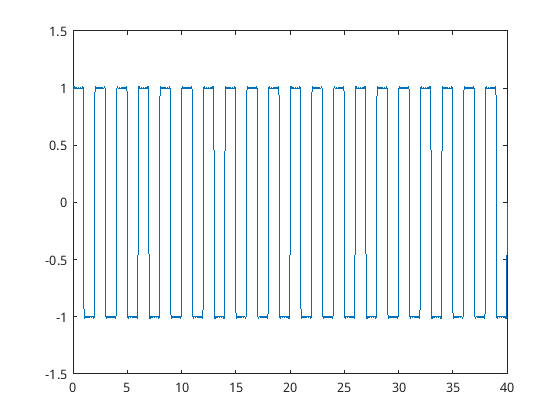

t = [0:0.01:40];

amplitude = 0;

kmax = 190;

result = 0;

yv = [1:0.01:40];

for i = [1:1:4001]
    result = 0;
    for k = [1:1:kmax]
        if mod(k , 2) == 0
            amplitude = 0;
        else
            amplitude = 4/(k*pi);
        end
        y = amplitude * sin(2*pi*50*k*t(1, i)*10e-3);
        result = result + y;
    end
    yv(1, i) = result;
end
figure
plot(t, yv)